clear
clc

%load robust control parameter D,rou,Q
D=[zeros(6);eye(6)];
rou=1000;
Q=[(1e4+2)/2e2*eye(6) 1/2e4*eye(6); 1/2e4*eye(6) (1e4+1)/2e6*eye(6)];

%load trajectory
load('tau.mat')
load('time.mat')
load('q.mat')

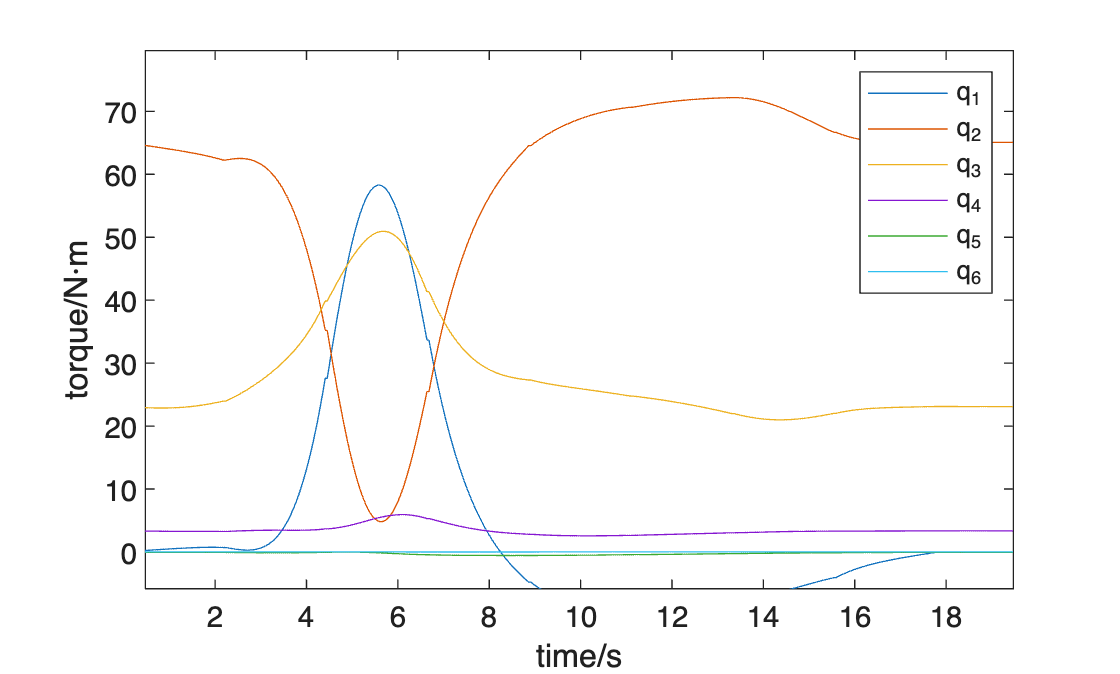


% add initial angle value
qd = zeros(2*450,6);
dqd = zeros(2*450-1,6);
ddqd = zeros(2*450-2,6);

for i = 1:6
    temp = q(:,i);
    for j = 1:450
        temp = [q(1,i);temp];
    end
    qd(:,i) = temp;
end

add_time = 0:0.5/450:0.5-0.5/450;
new_time = [add_time time+0.5]';

for i = 1:6
    ans = diff(qd);
    dqd(:,i) = ans(:,i)./diff(new_time);
end

for i = 1:6
    ans = diff(dqd);
    ddqd(:,i) = ans(:,i)./diff(new_time(1:899));
end

for i = 1:6
    plot(time(1,:),tau(i,:));
    hold on
end
ylabel('torque/N·m')
xlabel('time/s')
legend('q_1','q_2','q_3','q_4','q_5','q_6')
hold off

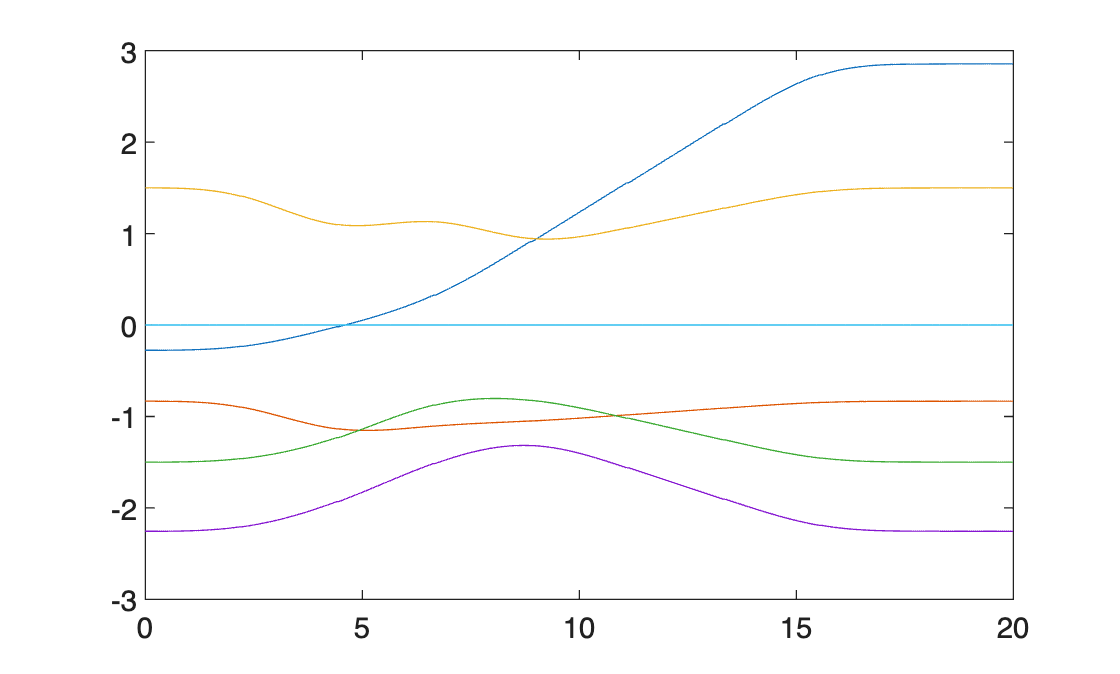

for i = 1:6
    plot(time(1,:),q(:,i));
    hold on
end
hold off